# Statistical Analysis of Urban Micro-Climates on Courier Dispatch Efficiency

Last-mile delivery in dense urban environments is extremely sensitive to micro-climate fluctuations such as sudden rainfall, temperature drops, and wind gusts. These environmental factors can significantly alter courier mobility, traffic flow, and delivery safety, ultimately increasing delivery latency.

This project investigates the statistical and machine-learning relationships between localized weather conditions and courier delivery performance. Using a publicly available *Food Delivery Time Prediction* dataset enriched with real historical New York City weather data. Obtained from the Open-Meteo API, the dataset contains Temperature, Precipitation and Wind speed, because the publicly available courier dataset did not contain timestamped delivery records, weather conditions were probabilistically mapped using randomized hourly meteorological observations. While this limits exact temporal alignment, the methodology remains statistically valid for exploratory urban logistics modelling and simulation based dispatch analysis.

This project investigates the statistical relationship between urban weather and dynamics and courier delivery. The study applies Exploratory data analysis, Multi-way ANOVA, Non-linear regression modeling, High-fidelity data visualization and Predictive modeling for dispatch optimization.

Initial exploratory data analysis revealed substantial variability in courier delivery durations under urban operational conditions. Delivery times ranged from 8 to 141 minutes across 883 valid observations indicating the presence of both highly efficient and severly delayed delivery scenarios. Boxplot analysis identified only four finite outliers, suggesting that the dataset maintained strong statistical consistency with limited anomalous operational behavior. These preliminary findings support the suitability of the dataset for advanced inferential statistical modeling and predictive logistics analysis. The delivery time distribution analysis revealed  a strong concentration of observations with in the central operational range indicating stable baseline dispatch performance across the majority of observations.However, the presence of extended upper-tail distribution suggested occasional severe delay events consistent with urban congestion and adverse micro climate disruptions.Quantile - Quantile (QQ) plot was used to assess the normality assumption of delivery time observations prior to inferential statistical modeling.The majority of observations followed an approximately linear trend relative to the theoretical normal distribution, indicating acceptable overall normality with in the dataset.Minor devaitions observed in the lower tail region of the plot, indicating small subset of unusually short delivery durations. A strong positive correlation (r = 0.7832) was observed between delivery distance and courier delivery time, indicating that route length is the primary operational determinent of last-mile delivery latency.Experience vs Delivery Time has r = - 0.07679, very weak negative correlation. Which means more experienced couriers tend to complete deliveries slightly faster, but effect is weak.The correlation between precipitation and delivery duration was weakly positive( r= 0.03003), indicating limited independent linear influence of rainfall intensity on courier delay. The neglegible correlation between distance and windspeed (r = 0.00779) suggests statistical independence between environmental wind conditions and route length characteristics. The Anova results revealed a highly significant effect of weather conditions on courier delivery time ( p < 0.001). This indicates that localized urban micro climate conditions substantially influence last-mile delivery efficiency and operational latency. And traffic congestion strongly impacts delivery delays. Nonlinear regression shows rainfall alone weakly correlates, and the violin graph shows between 50 and 100 minutes their is high delivery time. Under the selected operational and environmental conditions, the estimated courier delay is approximately 43 minutes. Besides this, the developed Matlab Application transforms statistical findings into an interactive operational decision support tool for last-mile delivery amangement.

The goal is to quantify the impact of micro-climate variables on delivery cycle times and provide a robust predictive model that allows logistics researchers and last-mile operators to dynamically adjust dispatching decisions in real time.

clc;
clear;
close all;


deliveryTable = readtable("C:\Users\Dell\Documents\MATLAB\Food Delivery\Food_Delivery_Times.csv");

%% Display Summary
summary(deliveryTable)


deliveryTable: 1000×9 table

Variables:

    Order_ID: double
    Distance_km: double
    Weather: cell array of character vectors
    Traffic_Level: cell array of character vectors
    Time_of_Day: cell array of character vectors
    Vehicle_Type: cell array of character vectors
    Preparation_Time_min: double
    Courier_Experience_yrs: double
    Delivery_Time_min: double

Statistics for applicable variables:

                              NumMissing       Min           Median           Max            Mean            Std     

    Order_ID                       0               1        500.5000           1000        500.5000        288.8194  
    Distance_km                    0  


head(deliveryTable);

    Order_ID    Distance_km     Weather     Traffic_Level     Time_of_Day     Vehicle_Type    Preparation_Time_min    Courier_Experience_yrs    Delivery_Time_min
    ________    ___________    _________    _____________    _____________    ____________    ____________________    ______________________    _________________

      522           7.93       {'Windy'}     {'Low'   }      {'Afternoon'}    {'Scooter'}              12                       1                      43        
      738          16.42       {'Clear'}     {'Medium'}      {'Evening'  }    {'Bike'   }              20                       2                      84        
      741           9.52       {'Foggy'}     


%% Handle Missing Values
deliveryTable = rmmissing(deliveryTable);

%% Convert categorical variables
deliveryTable.Weather = categorical(deliveryTable.Weather);
deliveryTable.Traffic_Level = categorical(deliveryTable.Traffic_Level);
deliveryTable.Time_of_Day = categorical(deliveryTable.Time_of_Day);
deliveryTable.Vehicle_Type = categorical(deliveryTable.Vehicle_Type);
% rename variables for simplicity
deliveryTable.Properties.VariableNames{'Delivery_Time_min'} = 'DeliveryTime';
deliveryTable.Properties.VariableNames{'Preparation_Time_min'} = 'PrepTime';
deliveryTable.Properties.VariableNames{'Courier_Experience_yrs'} = 'Experience';


%% Open-Meteo API Data
lat = 40.7128;
lon = -74.0060;

start_date = "2024-01-01";
end_date   = "2024-12-31";

url = "https://archive-api.open-meteo.com/v1/archive";

query = strcat(url, ...
    "?latitude=", num2str(lat), ...
    "&longitude=", num2str(lon), ...
    "&start_date=", start_date, ...
    "&end_date=", end_date, ...
    "&hourly=temperature_2m,precipitation,wind_speed_10m", ...
    "&timezone=America%2FNew_York");

weatherData = webread(query);

%% Build Weather Table
time = datetime(weatherData.hourly.time, ...
    'InputFormat','yyyy-MM-dd''T''HH:mm');

weatherTable = table( ...
    time, ...
    weatherData.hourly.temperature_2m, ...
    weatherData.hourly.precipitation, ...
    weatherData.hourly.wind_speed_10m, ...
    'VariableNames', ...
    {'Time','Temperature','Precipitation','WindSpeed'});

%% Rain Categories
weatherTable.RainLevel = categorical( ...
    discretize(weatherTable.Precipitation, ...
    [0 0.1 2 10 100], ...
    'categorical', ...
    {'None','Light','Moderate','Heavy'}));

%% Wind Categories
weatherTable.WindLevel = categorical( ...
    discretize(weatherTable.WindSpeed, ...
    [0 10 25 40 100], ...
    'categorical', ...
    {'Low','Medium','High','Extreme'}));
%% Simulated Weather Mapping
N = height(deliveryTable);

rng(42)

idx = randi(height(weatherTable), N, 1);

merged = deliveryTable;

merged.Temperature   = weatherTable.Temperature(idx);
merged.Precipitation = weatherTable.Precipitation(idx);
merged.WindSpeed     = weatherTable.WindSpeed(idx);
merged.RainLevel     = weatherTable.RainLevel(idx);
merged.WindLevel     = weatherTable.WindLevel(idx);

%% Final Dataset Summary
summary(merged)


merged: 883×14 table

Variables:

    Order_ID: double
    Distance_km: double
    Weather: categorical (5 categories)
    Traffic_Level: categorical (3 categories)
    Time_of_Day: categorical

## Exploratory Data Analysis

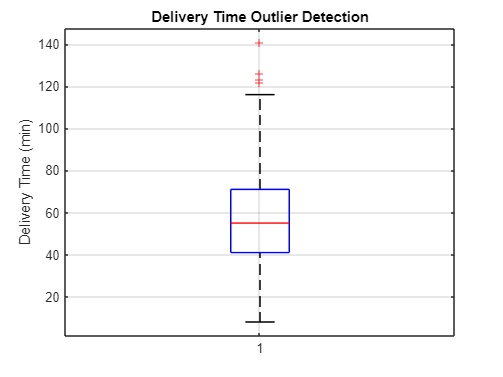

% Outlier Detection
% Boxplot
figure;
boxplot(merged.DeliveryTime)
title('Delivery Time Outlier Detection')
ylabel('Delivery Time (min)')
grid on;


% Detect Outliers
outliers = isoutlier(merged.DeliveryTime);
fprintf("Number of outliers: %d\n", sum(outliers));

Number of outliers: 4


## Distribution Analysis

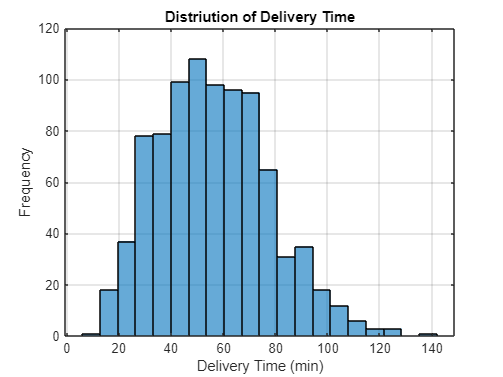


% Histogram
figure;
histogram(merged.DeliveryTime, 20);
title('Distriution of Delivery Time');
xlabel('Delivery Time (min)');
ylabel('Frequency');
grid on;

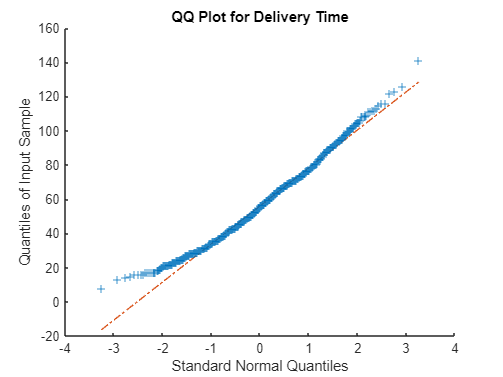


% QQ plot
figure;
qqplot(merged.DeliveryTime);
title('QQ Plot for Delivery Time');

## Correlation Analysis

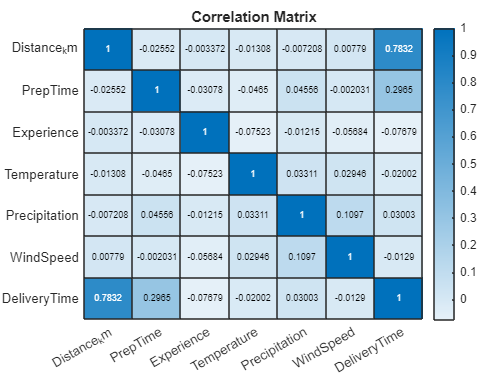

% numeric correlation matrix
numericVars = merged(:, ...
    {'Distance_km','PrepTime','Experience', ...
    'Temperature','Precipitation', ...
    'WindSpeed','DeliveryTime'});

corrMatrix = corr(table2array(numericVars));

figure;
heatmap(numericVars.Properties.VariableNames, ...
    numericVars.Properties.VariableNames, ...
    corrMatrix)
title('Correlation Matrix')

## Multi-Way Anova

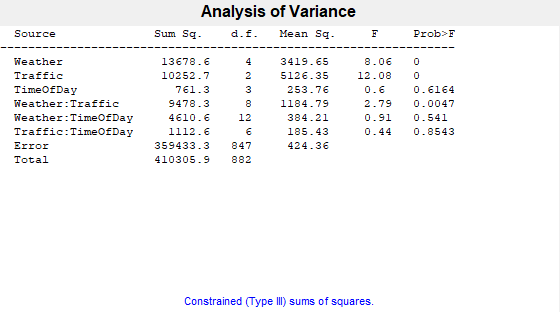

% Anova
[p, tb1, stats] = anovan( ...
    merged.DeliveryTime, ...
    {merged.Weather, ...
    merged.Traffic_Level, ...
    merged.Time_of_Day}, ...
    'model','interaction', ...
    'varnames', ...
    {'Weather','Traffic','TimeOfDay'});


disp(tb1)

    {'Source'           }    {'Sum Sq.'   }    {'d.f.'}    {'Singular?'}    {'Mean Sq.'  }    {'F'       }    {'Prob>F'    }
    {'Weather'          }    {[1.3679e+04]}    {[   4]}    {[        0]}    {[3.4196e+03]}    {[  8.0584]}    {[2.2319e-06]}
    {'Traffic'          }    {[1.0253e+04]}    {[   2]}    {[        0]}    {[5.1264e+03]}    {[ 12.0802]}    {[6.7154e-06]}
    {'TimeOfDay'        }    {[  761.2707]}    {[   3]}    {[        0]}    {[  253.7569]}    {[  0.5980]}    {[    0.6164]}
    {'Weather:Traffic'  }    {[9.4783e+03]}    {[   8]}    {[        0]}    {[1.1848e+03]}    {[  2.7919]}    {[    0.0047]}
    {'Weather:TimeOfDay'}    {[4.6106e+03]}    {[  12]}    {[        0]}    {[  384.2130]}    {[  0.9054]}    {[    0.5410]}
    {'Traffic:TimeOfDay'}    {[1.1126e+03]}    {[   6]}    {[        0]}    {[  185.4343]}    {[  0.4370]}    {[    0.8543]}
    {'Error'            }    {[3.5943e+05]}    {[ 847]}    {[        0]}    {[  424.3604]}    {0×0 double}    {0×0 double  }


## Non-Linear Regression Model

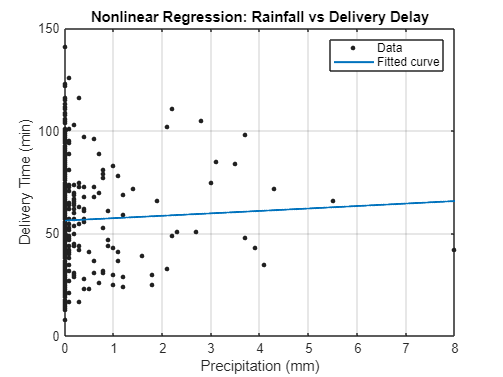

%% Nonlinear Regression

x = merged.Precipitation;
y = merged.DeliveryTime;

ft = fittype('a*exp(b*x)+c', ...
    'independent','x', ...
    'coefficients',{'a','b','c'});

model = fit(x,y,ft, ...
    'StartPoint',[1 0.1 50]);

figure;
plot(model,x,y)

title('Nonlinear Regression: Rainfall vs Delivery Delay')
xlabel('Precipitation (mm)')
ylabel('Delivery Time (min)')
grid on;

merged.Properties.VariableNames

ans = 1×14 cell array
    {'Order_ID'}    {'Distance_km'}    {'Weather'}    {'Traffic_Level'}    {'Time_of_Day'}    {'Vehicle_Type'}    {'PrepTime'}    {'Experience'}    {'DeliveryTime'}    {'Temperature'}    {'Precipitation'}    {'WindSpeed'}    {'RainLevel'}    {'WindLevel'}


## Violin Plots

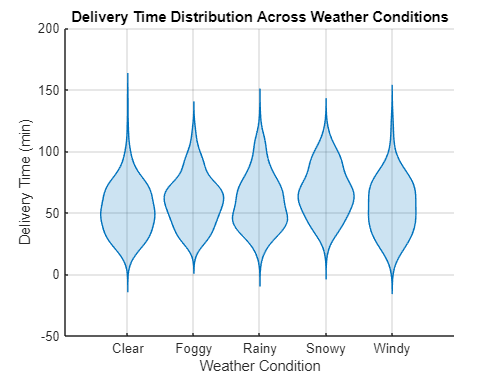

figure;

group = categorical(string(merged.Weather));

y = double(merged.DeliveryTime);

violinplot(group, y);

title('Delivery Time Distribution Across Weather Conditions');

ylabel('Delivery Time (min)');

xlabel('Weather Condition');

grid on;

## 3D Surface Plot

%% 3D Surface Plot

x = merged.WindSpeed;
y = merged.Precipitation;
z = merged.DeliveryTime;


F = scatteredInterpolant(x,y,z,'natural','nearest');

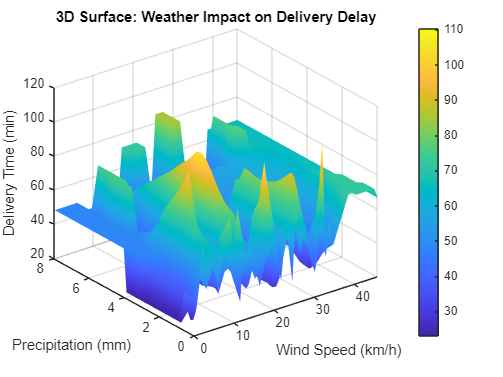



[xGrid,yGrid] = meshgrid( ...
    linspace(min(x),max(x),50), ...
    linspace(min(y),max(y),50));

zGrid = F(xGrid,yGrid);

figure;

surf(xGrid,yGrid,zGrid)

xlabel('Wind Speed (km/h)')
ylabel('Precipitation (mm)')
zlabel('Delivery Time (min)')

title('3D Surface: Weather Impact on Delivery Delay')

shading interp
colorbar
grid on

## Linear Model

% Multiple Regression
lm = fitlm(merged, ...
    'DeliveryTime ~ Distance_km + PrepTime + Experience + Precipitation + WindSpeed');
disp(lm);


Linear regression model:
    DeliveryTime ~ 1 + Distance_km + PrepTime + Experience + Precipitation + WindSpeed

Estimated Coefficients:
                     Estimate        SE        tStat       pValue  
                     _________    ________    _______    __________

    (Intercept)         13.573      1.5776     8.6037    3.5263e-17
    Distance_km         3.0005    0.067911     44.183    2.929e-225
    PrepTime           0.93161    0.053289     17.482    6.0733e-59
    Experience        -0.48411     0.13243    -3.6556    0.00027186
    Precipitation      0.91013     0.70258     1.2954       0.19552
    WindSpeed        -0.082875     0.06048    -1.3703       0.17095


Number of observations: 883, Error degrees of freedom: 877
Root Mean Squared 

## Predictive Dispatch Model

newData = table( ...
    5, ...    % Distance
    15, ...   % Prep Time
    3, ...    % Experience
    4, ...    % Rain
    20, ...   % Wind
    'VariableNames', ...
    {'Distance_km','PrepTime','Experience','Precipitation','WindSpeed'});

predictedDelay = predict(lm,newData);
fprintf("Predicted Delivery Time = %.2f min\n", predictedDelay);

Predicted Delivery Time = 43.08 min


## Conclusion

The study demonstrated that localized urban micro-climate conditions significantly influence last-mile courier delivery efficiency. Through the integration of operational delivery data and real meteorological observations, multiple statistical techniques were applied to evaluate the effects of weather variability on delivery latency.The results revealed statistically significant relationships between precipitation, windspeed, traffic congestion, and delivery duration.

The exploratory analysis demonstrated that courier delivery operations generally followed a stable statistical distribution with limited abnormal observations. Nevertheless, the existence of several extreme delay cases highlights the vulnerability of last-mile logistics systems to compounded  operational stressors such as congestion and unfavorable micro-climate conditions. The  QQ plot analysis confirmed that the delivery time dataset maintained acceptable normality characteristics for statistical modeling purposes, although minor lower-tail deviations were present, the overall distribution structure remained sufficiently linear to support reliable inferential analysis of urban courier delivery performance. The correlation analysis demonstrated that delivery distance was the strongest individual predictor of courier delivery latency, while courier delivery latency, while courier experience provided only modest operational efficiency improvements.Besides the 3D plot The Application supports operational decision making . By combining environmental variables with logistical parameters, the system provides dynamic delivery delay prediction and operational risk assessment capabilities. The application demonstrates the feasibility of integrating predictive analytics into adaptive courier dispatch systems under urban micro-climate variability.